**PUNTO 9**

**Importar datos como tabla temporal**

clearvars
clc
T = readtimetable("38_Industry_Portfolios.xlsx")

T = 1160×38 timetable
       date        Agric    Mines     Oil      Stone    Cnstr     Food     Smoke    Txtls    Apprl     Wood     Chair     Paper     Print    Chems    Ptrlm    Rubbr     Lethr    Glass    Metal    MtlPr    Machn    Elctr    Cars     Instr    Manuf    Trans    Phone     TV      Utils    Garbg     Steam     Water     Whlsl     Rtail    Money    Srvc 

**Defnir matriz binaria**

% Marcar rendimientos positivos como 1; y otro caso como 0
B = T;
B{:,:}(B{:,:} <= 0) = 0;
B{:,:}(B{:,:}  > 0) = 1;
B

B = 1160×38 timetable
       date        Agric    Mines    Oil    Stone    Cnstr    Food    Smoke    Txtls    Apprl    Wood    Chair    Paper    Print    Chems    Ptrlm    Rubbr    Lethr    Glass    Metal    MtlPr    Machn    Elctr    Cars    Instr    Manuf    Trans    Phone    TV    Utils    Garbg    Steam    Water    Whlsl    Rtail    Money    Srvc    Govt

**Calcular vector de rendimientos medios**

En principio, se calcula el vector de redimientos medios para cada uno de los 38 activos.

Vm = mean(T{:,:}, 1)

Vm =       -0.9144      0.95545       1.1791       1.1399       1.0578       0.9891        1.133      0.94519      0.97036      0.13439       1.1191       1.0218      0.90223       1.0504       1.0738       1.1966       1.0036      0.99666      0.96709       1.0024       1.1092       1.1532       1.1559       1.0539      0.83122      0.91953      0.77591       1.1884      0.87228      -47.029      -85.378      -98.811      0.84578        1.031       1.0105       1.0768      -50.484      -9.5455


Luego, el valor de umbral se define como la mediana del este vector: la cual actúa mejor que la media aritmética.

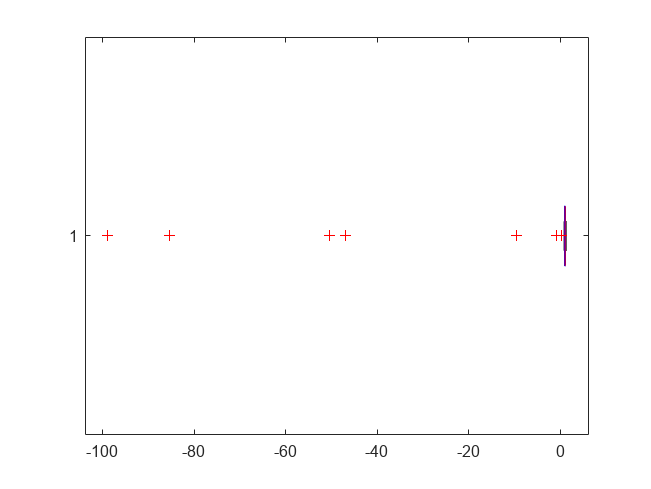

umbral = median(Vm);
boxplot(Vm, 'orientation','horizontal')

Ahora, se expresa este vector de forma binaria con cruce en el umbral.

Vb = zeros(numel(Vm),1);
Vb(Vm > umbral) = 1;
Vb = Vb'

Vb =      0     0     1     1     1     0     1     0     0     0     1     1     0     1     1     1     1     0     0     1     1     1     1     1     0     0     0     1     0     0     0     0     0     1     1     1     0     0


**Calcular métricas binarias**

A continuación, se calcula las métricas binarias de *Pearson*, *Jaccard *y *Dice*; estas métricas se promedian para obtener una medida de atipicidad del rendimiento de cada mes.

m = size(B,1);
index_medio = zeros(1,m);
for i = 1:m
    x = (B{i,:});
    y = Vb;
    [pearson, jaccard, dice] = Santy(x, y);
    index_medio(i) = mean([pearson, jaccard, dice]);
end

% Coeficientes infintios (NaN) se sustituyen por 1.
nan = (isnan(index_medio)');
index_medio(nan) = 1

index_medio =       0.31508      0.39569      0.27737      0.27545      0.52207      0.49214      0.41038      0.61603      0.29542      0.43721      0.45079      0.38094      0.48509      0.47862      0.51334      0.24225      0.51334      0.46437      0.20573      0.29566      0.51334      0.42315      0.38236      -0.0548      0.50708      0.42234      0.40961      0.47862      0.48509      0.29542      0.34176      0.33325      0.29566      0.38236    -0.013029      0.52207      0.45071      0.52207      0.15674      0.17715      -0.0548       0.4095      0.42234      0.50637      0.52207      0.35031      0.13016            1      0.56526      0.38142


**Distribución de frecuencias de las métricas binarias**

Al promedio de las métricas se le traza el diagrama de dispersión para identificar los meses con rendimientos atípicos. Esos mesos corresponden al *outlier* del diagrama.

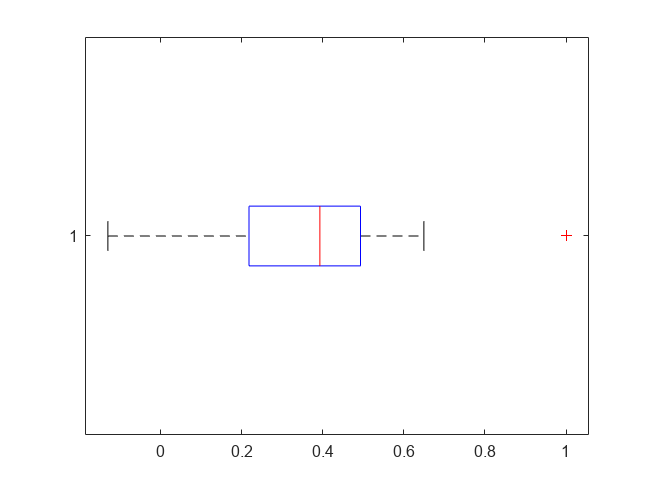

boxplot(index_medio, Orientation="horizontal")

pos_atipicos = find(nan)'

pos_atipicos =           48          51          63          66          71          80          97         135         141         167         236         243         269         288         430         431         432         435         468         482         512         517         526         619         628         640         645         668         695         736         915         988        1007        1023        1110        1115        1124        1125        1152        1155


Finalmente, se filtra la tabla para que mostrar los meses con rendimientos atípicos

Tabla_atipicos = T;
Tabla_atipicos(~nan,:) = []

Tabla_atipicos = 40×38 timetable
       date        Agric     Mines      Oil      Stone     Cnstr      Food     Smoke     Txtls     Apprl      Wood     Chair     Paper     Print     Chems     Ptrlm     Rubbr     Lethr     Glass     Metal     MtlPr     Machn     Elctr      Cars     Instr     Manuf     Trans     Phone       TV      Utils     Garbg     Steam     Water     Whlsl     Rtail     Money

**Función de métricas binarias**

function [pearson, jaccard, dice] = Santy(A,B)
    a = sum(A + B == 2);
    b = sum(A==0 & B==1);
    c = sum(A==1 & B==0);
    d = sum(A + B == 0);
    pearson = (a*d-b*c) / sqrt((a+c)*(b+d)*(a+b)*(c+d));
    jaccard = a / (a+b+c);
    dice = 2*a / (2*a+b+c);
end
